ANOVA TestBench on 2lvl full factorial

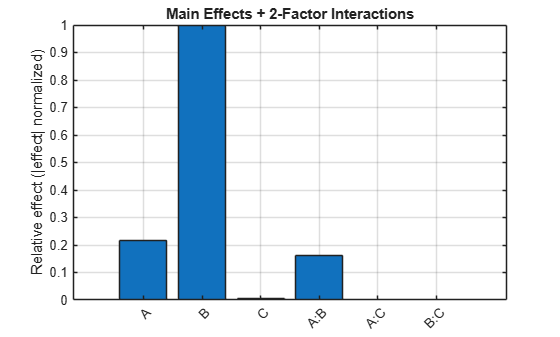

clear; clc; close all;

% --- Factors / levels (not important; choose simple 2-level) ---
varNames   = {'A','B','C'};
lowLevels  = [1, 2, 3];
highLevels = [ 10,  20,  30];

% --- Build 2-level full factorial design (actual levels) ---
D = make_design_2lvl_fullfact(varNames, lowLevels, highLevels, "design_ABC.txt");

% --- Synthetic "simulation" response ---
A = D(:,1); B = D(:,2); C = D(:,3); %>  % C unused in f(), on purpose
Y = A + B.^2 + A.*B + C/10 + 1e-6*randn(size(A));

% (Optional) write results so it matches your real workflow
writematrix(Y, "results_ABC.txt", 'Delimiter','tab');

% --- Sensitivity analysis: main + 2-factor interactions ---
statsOut = analyze_2lvl_fullfact_interactions(varNames, lowLevels, highLevels, ...
    "design_ABC.txt", "results_ABC.txt", 1);


% --- Print ranked effects ---
[~, order] = sort(abs(statsOut.effects), 'descend');
disp('Ranked effects (largest magnitude first):');

Ranked effects (largest magnitude first):


disp(table(string(statsOut.labels(order))', statsOut.effects(order)', statsOut.pValues(order)', ...
    'VariableNames', {'Term','Effect','pValue'}));

    Term       Effect       pValue
    _____    ___________    ______

    "B"              495     NaN  
    "A"              108     NaN  
    "A:B"             81     NaN  
    "C"              2.7     NaN  
    "A:C"    -6.5802e-07     NaN  
    "B:C"     3.3372e-07     NaN  

